# Code: Analytical derivation of non-linearity due to uncertainty in measurement time

Here we show proof that a system's response can appear non-linear due to uncertainty in the time of measurements of the system's input. 

by Nithin Sivadas

**Note: Please do not share without Nithin's explicit permission. **

**For submission to the Journal Science. **

Updated: 7th Oct 2021; 6th Aug 2021; Dec 25th; Jan 5th

29 Dec 2021 - Added validation with Monte-Carlo method

outputFolder = 'G:\My Drive\Research\Projects\Paper 6\Draft\Version 4\NatCom\Figures\';

## Definitions

Here we attempt to develop an analytical/numerical solution for the conditional probability density of $X$ given $W$. As above, 


$$W = X(t+\Delta)$$



$$X \sim f_X(x)$$



$$\Delta \sim f_\Delta(\delta)$$


In our case, $f_X(x)$ is defined to be a lognormal function, and $f_{\Delta}(\delta)$is a gaussian distribution. More on this later. 

Assuming the process is stationary, and $X$ and $\Delta$ are independent, we get 

$f_W(w) = f_X(w)$       $\rightarrow$(eq.1)

A lognormal random variable $X$ can also be converted to a gaussian random variable $Z
$. 

Where, $Z \sim \phi(z,\mu_Z,\sigma_Z)$ and $Y = \log X$

Here,  $\phi(x,\mu,\sigma) = \frac{1}{\sqrt{2\pi}\sigma} e^{-\frac{(x-\mu)^2}{2\sigma^2 }}$  $$ \rightarrow$
$(eq.2), General normal distribution

phi = @(x,m,s) s.^-1.*(2.*pi).^-0.5.*(exp(-0.5*(s.^-1.*(x-m)).^2));

and $X(t)\sim f_X(x) = \frac{1}{x(t)}\phi(\log x(t), \mu_Z,\sigma_Z)$

fx = @(x,m,s) x.^-1.*phi(log(x),m,s);

$\mu_X, \sigma_X
$ are known, and are related to $\mu_Z, \sigma_Z
$ in the following manner

$\mu_Z = \log \Bigg( \frac{\mu_X^2}{\sqrt{\mu_X^2 + \sigma_X^2}} \Bigg)$$\rightarrow$ (eq.3)

$\sigma_Z = \sqrt{\log \Bigg( 1 + \frac{\sigma_X^2}{\mu_X^2} \Bigg)}$$\rightarrow$ (eq.4)

mz = @(m,s) log(m.^2.*(m.^2 + s.^2).^-0.5);
sz = @(m,s) (log(1+(s./m).^2)).^0.5;

$X(t)
$is autocorrelated to itself, and its autocorrelation coefficient is


$$\rho_X(\delta,k) = e^{-\frac{|\delta|}{k}}$$


$k
$** is the autocorrelation time constant**

rhox = @(d,k) exp(-abs(d)./k);

the corresponding autocorrelation of the normal random variable $Y
(t)$ is


$$\rho_Z(\delta,k) = \frac{1}{\sigma_Z^2}\log(1+\rho_X(\delta,k)[e^{\sigma_Z^2}-1])$$


rhoz = @(d,sz,k) sz.^-2.*log(1+rhox(d,k).*(exp(sz.^2)-1));

In addition, the random time delay follows a zero mean gaussian distribtion


$$f_\Delta(\delta) = \phi(\delta/\sigma_\delta)$$


fD = @(d,s) phi(d,0,s);

$\sigma_\delta

$** is a measure of the uncertainty in the random time delay **$\Delta
$

## Derivation

From eq.1 we can derive 

$f_{X|W}(x|w) = f_{W|X}(w|x) \frac{f_X(x)}{f_X(w)}$    $\rightarrow$(eq.5)

Also, 

$f_{W|X}(w|x) = \int_{-\infty}^{\infty} f_{ W | X, \Delta }(w|x, \delta ) f_{\Delta}( \delta) d \delta \ \ \ \rightarrow
 $(eq.6)

Now from eq.2 and bi-variate lognormal distribution, we get, 

$f_{ W | X, \Delta }(w|x, \delta )  =  \frac{1}{x_2} \phi \Big( \log w, \ 
\mu_{Z} + \rho_{Z}(\delta)[\log x - \mu_Y], \ 
\sigma_{Z} \sqrt{1-\rho_Z^2(\delta)} \Big) \rightarrow
$(eq.7)

fwgxd = @(w,x,d,mz,sz,k) w.^-1.*phi(log(w),mz+rhoz(d,sz,k).*(log(x)-mz),sz.*(1-(rhoz(d,sz,k)).^2).^0.5); % eq.7
fwgx = @(w,x,my,sz,k,sd) integral(@(d) fwgxd(w,x,d,my,sz,k).*fD(d,sd),-inf,inf,'ArrayValued',true); % eq.6

### Numerical Integration

Finally, from eq.5, eq.6, and eq.7, and taking the first moment of the distribution and normalizing it, we get 

$\langle X|W=w \rangle = \frac{\int_0^\infty xf_{X|W}(x|w) \mathrm{d}x}{\int_0^\infty f_{X|W}(x|w) \mathrm{d}x} $ $\rightarrow$ (eq.8) 

The conditional expectation of X|W, is the best estimate of $X$ we have given the erroneous measurement $W$. 

Since the integral is challenging to do analytically, we resort to numerical integration. 

Fxgw = @(w,x,mx,sx,k,sd) fwgx(w,x,mz(mx,sx),sz(mx,sx),k,sd).*fx(x,mz(mx,sx),sz(mx,sx))./(fx(w,mz(mx,sx),sz(mx,sx))); %eq.5
nFxgw = @(w,x,mx,sx,k,sd) Fxgw(w,x,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); 
Exgw = @(w,mx,sx,k,sd) integral(@(x) x.*Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true);
nExgw = @(w,mx,sx,k,sd) Exgw(w,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); %eq.8

## Likelihood function given a specific delay$F_{W|X,\Delta}(w|x,\delta)
$

Key point here is that $F_{W|X,\Delta}(w|x,\delta) = f(\delta/k,x)
$ , is a function of the ratio $\delta/k
$. This can be seen in eq.7, combined with the formula for $\rho_Z(\delta,k) 
$ and $\rho_X(\delta,k) $, which are both just functions of $\rho_Z(\delta/k) $ and $\rho_X(\delta/k) $. 

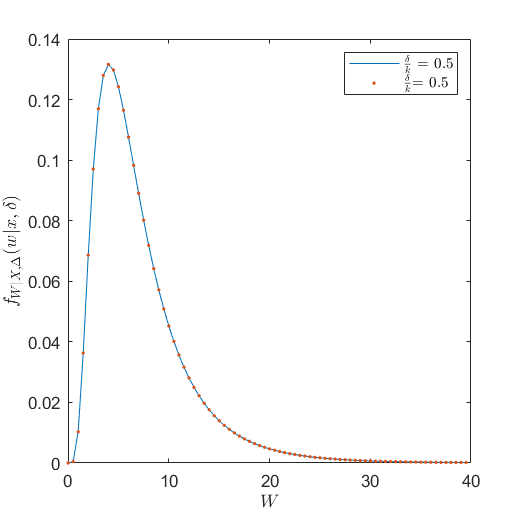

fig1=figure;
resize_figure(fig1,2*55,2*55);
% mx = -0.25; %1.125
% sx = 0.85; % 1.1488
mx = 1.12; % -0.2517
sx = 1.15; % 0.8516
xbin = 0.01:0.5:40;
d = 1;
k = 2;
plot(xbin,fwgxd(xbin,15,5,mz(mx,sx),sz(mx,sx),10));
hold on;
plot(xbin,fwgxd(xbin,15,d,mz(mx,sx),sz(mx,sx),k),'.');
set(gca,'XScale','linear');
xlabel('$W$','Interpreter','latex');
ylabel('$f_{W|X,\Delta}(w|x,\delta)$','Interpreter','latex');
legend('$\frac{\delta}{k}$ = 0.5',['$\frac{\delta}{k}$= ',num2str(d/k,2)],'Interpreter','latex');

## Likelihood function$F_{W|X}(w|x)
$

By integrating away $\delta
$, we get $F_{W|X}(w|x)
 = f(\sigma_{\delta}/k,x)
$ , is a function of the ratio $\sigma_\delta/k
$. This is a result of the integration in eq.6, which is challenging to do analytically. As a result it is surprising that it a function of the ratio $\sigma_\delta/k
$, which we call here the **effective temporal uncertainty**.  

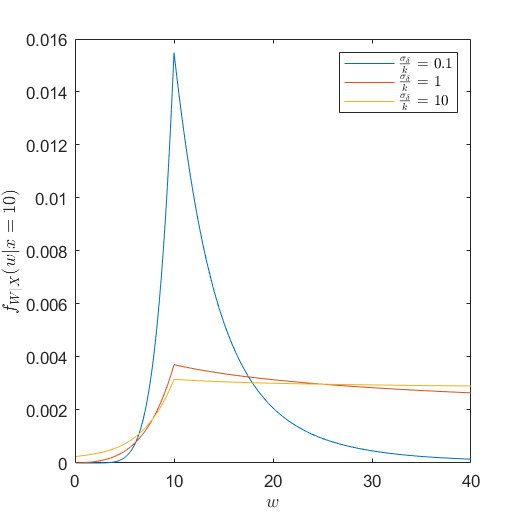

fig2=figure;
resize_figure(fig2,2*55,2*55);
% mx = -0.25;
% sx = 0.85;
xbin = 0.1:0.1:40;
ratio1 = 0.1;
ratio2 = 1; % k/sd
ratio3 = 10;
y1 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio1);
y2 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio2);
y3 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio3);
plot(xbin,y1./trapz(y1)); % Note: we are plotting normalized pdfs 
hold on;
plot(xbin,y2./trapz(y2));
hold on;
plot(xbin,y3./trapz(y3));
xlabel('$w$','Interpreter',"latex");
ylabel('$f_{W|X}(w|x=10)$','Interpreter','latex')
legend(['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)],'Interpreter','latex');
set(gca,'XScale','linear');

## Posterior probability distribution$F_{X|W}(x|w)
$

From eq.5, eq.6, and eq.7, we $F_{X|W}(x|w)
 = f(\sigma_{\delta}/k,w)
$ , which also remains a function of the ratio $\sigma_\delta/k
$. As the **effective temporal uncertainty** decreases, the probability that $X
$ (a.k.a true value) is close to what is measured $W$increases. 

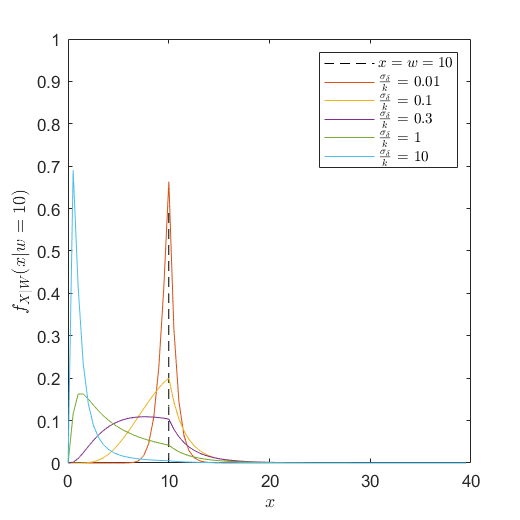

fig3=figure;
resize_figure(fig3,2*55,2*55);
% mx = -0.25;
% sx = 0.85;
xbin = 0.01:0.5:40;
ratio = 0.01; % sd/k
ratio1 = 0.1;
ratio2 = 0.3;
ratio3 = 1;
ratio4 = 10;
plot(10.*ones(1,10),linspace(0,0.6,10),'--k');
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio1));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio2));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio3));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio4));
xlabel('$x$','Interpreter',"latex");
ylabel('$f_{X|W}(x|w=10)$','Interpreter','latex')
legend( '$x=w=10$',...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio)],...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio4)], ...
    'Interpreter','latex');
set(gca,'XScale','linear');
xlim([0 40])
ylim([0 1])

wbin = 0.01:0.5:40;
xbin = 0.01:0.5:40;
Z = zeros(length(wbin),length(xbin));
for i = 1:length(wbin)
    Z(i,:)=nFxgw(wbin(i),xbin,mx,sx,1,ratio2);
end

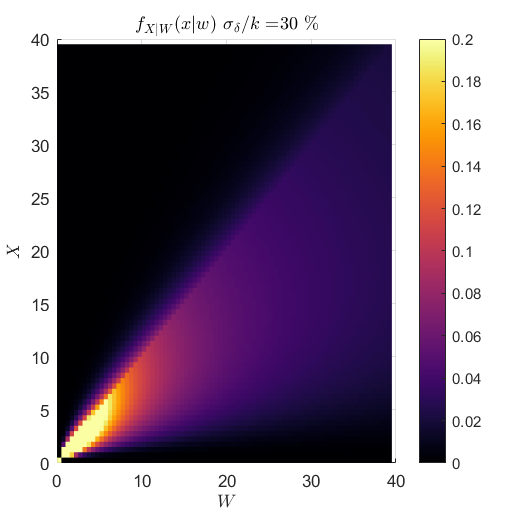

fig4=figure;
resize_figure(fig4,2*55,2*55);
colormap('inferno');
surf(wbin,xbin,Z','EdgeColor','none');
view(2);
xlabel('$W$','Interpreter','latex');
ylabel('$X$','Interpreter','latex');
colorbar();
set(gca,'ColorScale','linear');
caxis([0 0.2]);
title(['$f_{X|W}(x|w)$ $\sigma_\delta/k = $',num2str(100*ratio2),' \%'],'Interpreter','latex');
xlim([0,40]);
ylim([0,40]);

## Result: Non-linearity in $$\langle X|W \rangle$$increases with effective temporal uncertainty $\sigma_\delta /k$

The figure shows, non-linearity increasing with effective temporal uncertainty. This proves the claim that "uncertainty in measurement time can create a perception of non-linear bias in the systems response", if $X
$ drives some output $Y_{out}
$, and we regress $Y_{out}
$ with $X$. Furthermore, if $X$ propagates through a system, and$W=X(t+\Delta)
$ is read as output at the other end, then this system's response can apprear to be non-linear - especially if there is more than $$10\%$$ effective temporal uncertainty. For a 30% temporal uncertainty, the true regression function is at least 400% higher than when the function saturates at the highest value of the erroneous input $W=40$ units. 

wbin = 1:2:40;
xT = zeros(1,length(wbin));
xT1 = nExgw(wbin,mx,sx,100,1);
xT2 = nExgw(wbin,mx,sx,10,1);
xT3 = nExgw(wbin,mx,sx,3,1);
xT4 = nExgw(wbin,mx,sx,1,1);
xT5 = nExgw(wbin,mx,sx,0.5,1);

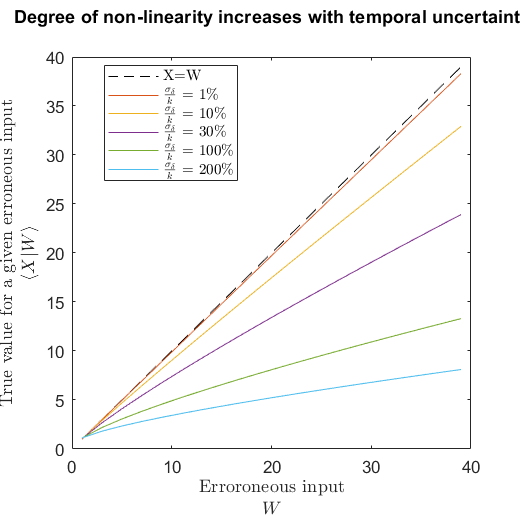

figM4=figure;
resize_figure(figM4,2*55,2*55);
plot(wbin,wbin,'--k');
hold on;
plot(wbin,xT1);
hold on;
plot(wbin,xT2);
hold on;
plot(wbin,xT3);
hold on;
plot(wbin,xT4);
hold on;
plot(wbin,xT5);
title('Degree of non-linearity increases with temporal uncertainty',' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'True value for a given erroneous input','$\langle X|W \rangle$'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $200\%$'], ...
    'Interpreter','latex','Location','Best');
% export_fig([outputFolder,'FigureM4.png'], ...

%     '-r600','-png','-nocrop',figM4);
% export_fig([outputFolder,'FigureM4.pdf'], ...
%     '-r600','-pdf','-nocrop',figM4);

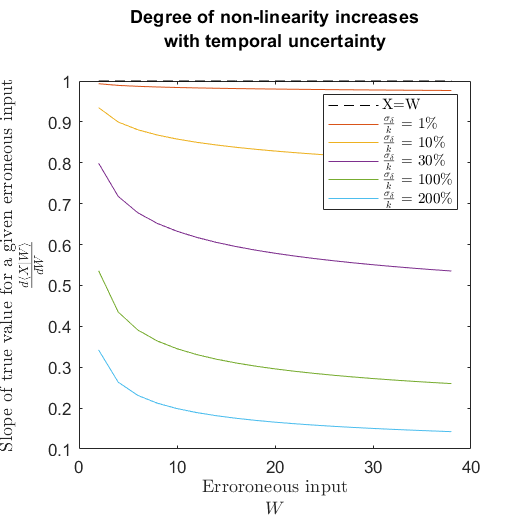

figA1=figure;
resize_figure(figA1,2*55,2*55);
mwbin = 0.5.*(wbin(1:end-1)+wbin(2:end));
plot(mwbin,diff(wbin)./diff(wbin),'--k');
hold on;
plot(mwbin,diff(xT1)./diff(wbin));
hold on;
plot(mwbin,diff(xT2)./diff(wbin));
hold on;
plot(mwbin,diff(xT3)./diff(wbin));
hold on;
plot(mwbin,diff(xT4)./diff(wbin));
hold on;
plot(mwbin,diff(xT5)./diff(wbin));
title({'Degree of non-linearity increases','with temporal uncertainty'},' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'Slope of true value for a given erroneous input','$\frac{d\langle X|W \rangle}{dW} $'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $200\%$'], ...
    'Interpreter','latex','Location','northeast');

% export_fig([outputFolder,'FigureM4_1.png'], ...
%     '-r600','-png','-nocrop',figA1);
% export_fig([outputFolder,'FigureM4_1.pdf'], ...
%     '-r600','-pdf','-nocrop',figA1);

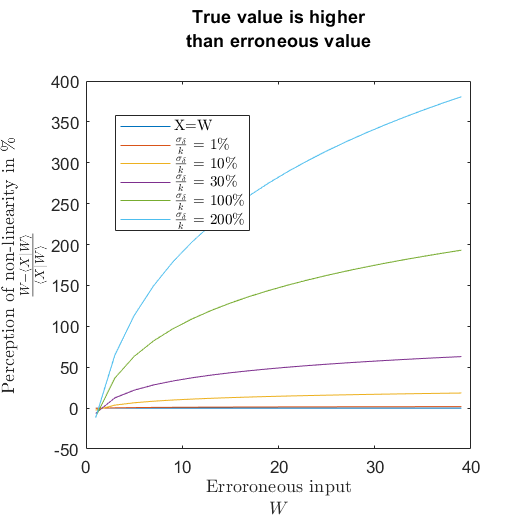

figA2=figure;
resize_figure(figA2,2*55,2*55);
plot(wbin,100.*(wbin./wbin-1));
hold on;
plot(wbin,100.*(wbin./xT1-1));
hold on;
plot(wbin,100.*(wbin./xT2-1));
hold on;
plot(wbin,100.*(wbin./xT3-1));
hold on;
plot(wbin,100.*(wbin./xT4-1));
hold on;
plot(wbin,100.*(wbin./xT5-1));
title({'True value is higher','than erroneous value'},' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'Perception of non-linearity in $\%$','$\frac{W-\langle X|W \rangle}{\langle X|W \rangle} $'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $200\%$'], ...
    'Interpreter','latex','Location','best');

% export_fig([outputFolder,'FigureM4_2.png'], ...
%     '-r600','-png','-nocrop',figA2);
% export_fig([outputFolder,'FigureM4_2.pdf'], ...
%     '-r600','-pdf','-nocrop',figA2);


## Monte-Carlo validation

Validating the results of the analytical derivation with that of a Monte-Carlo simulation. 

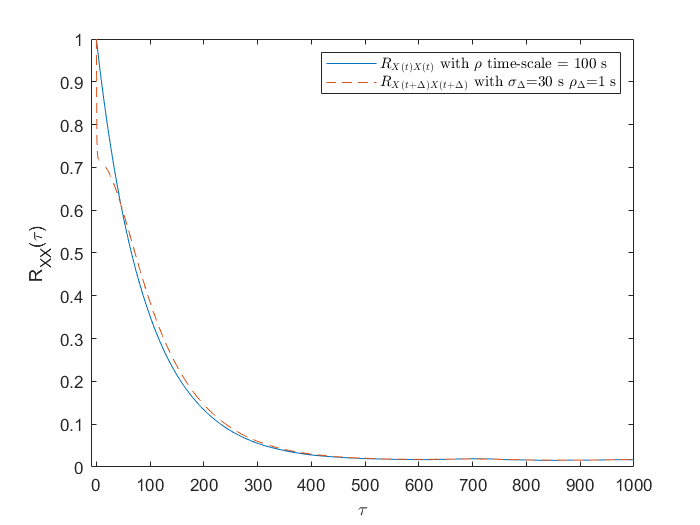

dt = 1;
nSamples = 2^12;
nEnsembles = 10000;
lag = fftshift(-nSamples:1:nSamples-1)'.*dt;

tau = 100; % Autocorrelation time constant k
Rm = acf(abs(lag),tau);
RmMatrix = toeplitz(Rm(find(lag==0):find(lag==(nSamples-1)*dt)));
X = MvLogNRand(repmat(-0.2518,nSamples,1),repmat(0.85,nSamples,1),nEnsembles,RmMatrix);

deltaT = 30; % Standard deviation of time uncertainty: sigma_D 
tau_D = 1; % The autocorrelation time constant of the time uncertainty
Rmd = acf(abs(lag),tau_D);
RmdMatrix = toeplitz(Rmd(find(lag==0):find(lag==(nSamples-1)*dt)));
D = mvnrnd(zeros(1,nSamples),corr2cov(repmat(deltaT,nSamples,1), RmdMatrix),nEnsembles);

time = ((1:1:nSamples).*dt-1);
scatteredTime = time + D; 
scatteredTime(scatteredTime<0) = nSamples + scatteredTime(scatteredTime<0);
scatteredTime(scatteredTime>nSamples-1) = scatteredTime(scatteredTime>nSamples-1) - (nSamples-1);
W = zeros(nEnsembles,nSamples);
time1 = zeros(1,nSamples+2);
time1(1) = -1;
time1(2:end-1) = time;
time1(end) = time(end)+1;
X1 = zeros(nEnsembles,nSamples+2);
X1(:,1) = X(:,end);
X1(:,2:end-1) = X(:,1:end);
X1(:,end) = X(:,1);
for i=1:1:nEnsembles
    W(i,:) = interp1(time1,X1(i,:),scatteredTime(i,:));
end

M = W;
[RArrayXN,lagXN] = find_correlation(M-nanmean(M,1),nSamples,nEnsembles,1);

acf_W = mean(RArrayXN(:,1:2^12)./RArrayXN(:,1));
lag_W = lagXN(1:2^12);
acf_fit_W = fit(lag_W,acf_W','spline'); % Fitting the ACF with a spline!

M = X;
[RArrayXN1,lagXN] = find_correlation(M-nanmean(M,1),nSamples,nEnsembles,1);

acf_X = mean(RArrayXN1(:,1:2^12)./RArrayXN1(:,1));
lag_X = lagXN(1:2^12);
acf_fit_X = fit(lag_X,acf_X','spline'); % Fitting the ACF with a spline!

figure; 
tInd = 0:1000;
% plot(tInd,acf(tInd,tau));
% hold on;
plot(tInd,acf_fit_X(tInd));
hold on;
plot(tInd,acf_fit_W(tInd),'--');
xlabel('\tau');
ylabel('R_{XX}(\tau)');
legend(['$R_{X(t)X(t)}$ with $\rho$ time-scale = ',num2str(tau),' s'], ...
    ['$R_{X(t+\Delta)X(t+\Delta)}$ with $\sigma_{\Delta}$=',num2str(deltaT),' s', ...
    ' $\rho_{\Delta}$=',num2str(tau_D),' s'],'Interpreter','latex');
xlim([-10,1000]);

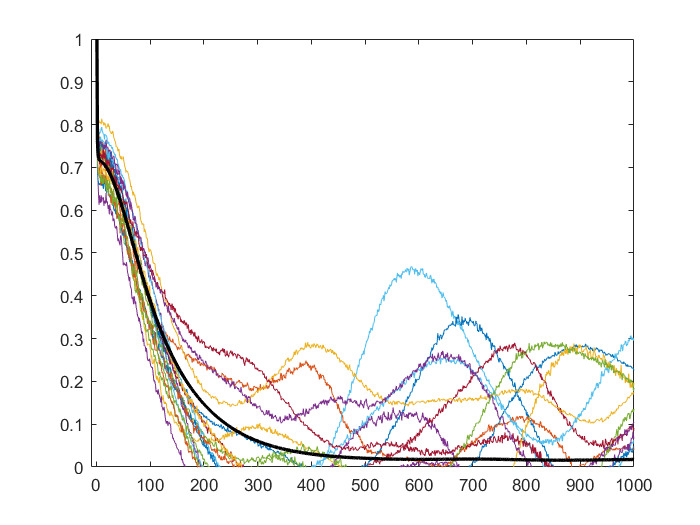

figure;
plot(RArrayXN(2:20,1:2^12)'./RArrayXN(2:20,1)');
hold on;
plot(mean(RArrayXN(:,1:2^12)./RArrayXN(:,1)),'k','LineWidth',2);
ylim([0,1]);
xlim([-10,1000]);

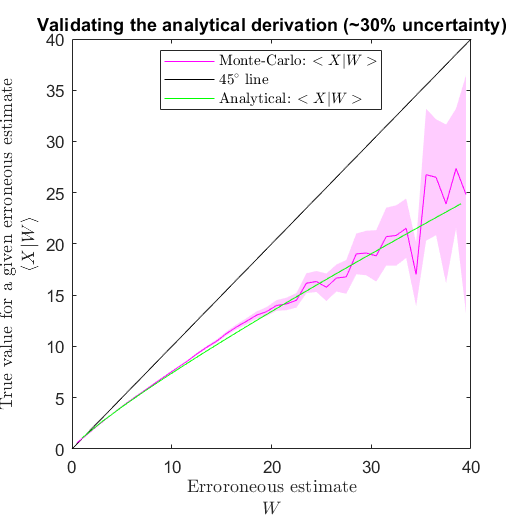

XBins = 0:1:40;
EXgW = create_curve(W(:),X(:),XBins);

figM2=figure;
resize_figure(figM2,2*55,2*55);
p0 = plot(XBins,XBins,'-k');
hold on;
p1 = plot_curve(EXgW,'m'); % model
hold on;
p2=plot(wbin,xT3,'g');

ylim([0,40]);
xlim([0,40]);
xlabel({'Erroroneous estimate','$W$'},'Interpreter','Latex');
ylabel({'True value for a given erroneous estimate','$\langle X|W \rangle$'},'Interpreter','Latex');
legend([p1,p0,p2],...
    'Monte-Carlo: $<X|W>$',...
    '45$^\circ$ line', ...
    'Analytical: $<X|W>$',...
    'Interpreter',"latex",'Location','best');
title('Validating the analytical derivation (~30% uncertainty)','Interpreter',"none");

The above plot shows that the analytical derivation results in the same non-linearly biased regression function as that generated from the monte-carlo simulation. 

function RmArray=acf(lag,tau)

    RmArray = exp(-abs(lag).*tau.^-1);

end

function [edges, value] = create_segmented_pdfs(X,Y,XBins,XSegments,normalizationStr)

**create_segmented_pdfs(): **Creating histograms of probability distributions, which can be colored to show a form of conditional probability distribution. (See figure).

if nargin<5
    normalizationStr = 'countdensity';
end

value = zeros(length(XSegments),length(XBins)-1);
for i=1:1:length(XSegments)
    if i==1
        [value(i,:),edges] = histcounts(Y(X<=XSegments(i)),XBins,'Normalization',normalizationStr);
        edges = edges(2:end) - (edges(2)-edges(1))/2;
    elseif i>1 && i < length(XSegments)
        value(i,:) = histcounts(Y(X>XSegments(i-1) & X<=XSegments(i)),XBins,'Normalization',normalizationStr);
    else
       value(i,:) = histcounts(Y(X>=XSegments(i-1)),XBins,'Normalization',normalizationStr);
    end
    
end

end


function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function p = plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function [fXgY,XX,YY] = conditional_pdf(X, Y, gridx, gridy)

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

sz = 2^10;
Y = Y(:);
Y(Y==999999)=nan;

[bandwidth,fXY,XX,YY]=kde2d([X,Y],sz,[min(gridx),min(gridy)],[max(gridx),max(gridy)]);
[fY, YY1] = ksdensity(Y,YY(:,1));

fXgY = fXY./repmat(fY,1,sz);


The above formula is basically equation 1, below. 

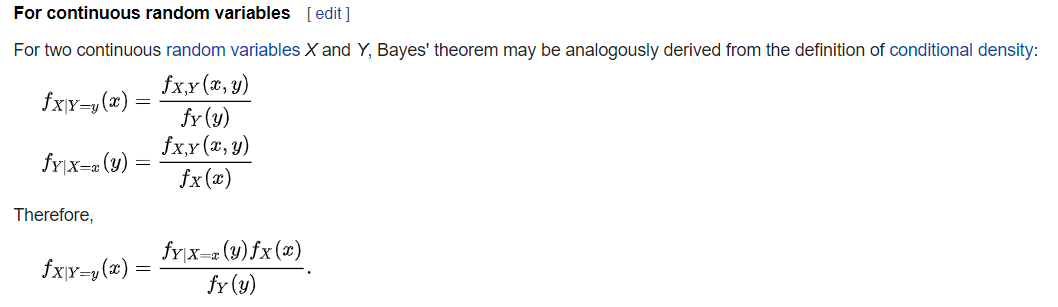


end


function [M, nSample, nEnsemble]= split_series(series,sampleSize,MaxNoOfMissingValues)
    if nargin<3
        MaxNoOfMissingValues=1000;
    end
        
    series = padarray(series,sampleSize-mod(length(series),sampleSize),'post');
    L = length(series); 
    M0 = reshape(series,sampleSize,[])';
    indx=sum(isnan(M0),2)>MaxNoOfMissingValues;
    l = 1:1:size(M0,1);
    k=1;
    for i=l(~indx)
        M(k,:) = M0(i,:);
        k=k+1;
    end
    nSample = size(M,2);
    nEnsemble = size(M,1);
    
    M = interp_nans(M')';
end

function [RArray,lag]=find_correlation(M,nSample,nEnsemble,sampleTime)
    dt = sampleTime;
    lag = fftshift(-nSample:1:nSample-1)'.*dt;
    xCell = mat2cell(M, ones(1,nEnsemble),nSample);
    [RArray] = cellfun(@(x) xcorr(x,'unbiased'),xCell,'UniformOutput',false);
    RArray = cell2mat(RArray);
    RArray(:,2:end+1) = RArray(:,1:end);
    RArray(:,1)=RArray(:,2);
    RArray = ifftshift(RArray);
end



## External Functions

Acknowledging the use of two external functions: 

1) Stephen Lienhard (2021). Multivariate Lognormal Simulation with Correlation (https://www.mathworks.com/matlabcentral/fileexchange/6426-multivariate-lognormal-simulation-with-correlation), MATLAB Central File Exchange. Retrieved October 7, 2021.

2) Zdravko Botev (2021). kernel density estimation (https://www.mathworks.com/matlabcentral/fileexchange/17204-kernel-density-estimation), MATLAB Central File Exchange. Retrieved October 7, 2021.

### Stochastic process from Log-normal distribution

MVLOGNRAND MultiVariant Lognormal random numbers with correlation

function y = MvLogNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = exp( mvnrnd( Mu , covv , Simulations ));
end

function y = MvNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = mvnrnd( Mu , covv , Simulations );
end

function y = MvtRand( Mu , Nu , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end

% Force column vectors
Mu     = Mu(:);
% Calculate the covariance structure
% sigma_down = repmat( Sigma' , numel(Sigma), 1            );
% sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
% covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
%                        sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = Mu' + mvtrnd(CorrMat, Nu, Simulations);
end

### KDE2D

fast and accurate state-of-the-art bivariate kernel density estimator with diagonal bandwidth matrix.

function [bandwidth,density,X,Y]=kde2d(data,n,MIN_XY,MAX_XY)
% fast and accurate state-of-the-art
% bivariate kernel density estimator
% with diagonal bandwidth matrix.
% The kernel is assumed to be Gaussian.
% The two bandwidth parameters are
% chosen optimally without ever
% using/assuming a parametric model for the data or any "rules of thumb".
% Unlike many other procedures, this one
% is immune to accuracy failures in the estimation of
% multimodal densities with widely separated modes (see examples).
% INPUTS: data - an N by 2 array with continuous data
%            n - size of the n by n grid over which the density is computed
%                n has to be a power of 2, otherwise n=2^ceil(log2(n));
%                the default value is 2^8;
% MIN_XY,MAX_XY- limits of the bounding box over which the density is computed;
%                the format is:
%                MIN_XY=[lower_Xlim,lower_Ylim]
%                MAX_XY=[upper_Xlim,upper_Ylim].
%                The dafault limits are computed as:
%                MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
%                MAX_XY=MAX+Range/4; MIN_XY=MIN-Range/4;
% OUTPUT: bandwidth - a row vector with the two optimal
%                     bandwidths for a bivaroate Gaussian kernel;
%                     the format is:
%                     bandwidth=[bandwidth_X, bandwidth_Y];
%          density  - an n by n matrix containing the density values over the n by n grid;
%                     density is not computed unless the function is asked for such an output;
%              X,Y  - the meshgrid over which the variable "density" has been computed;
%                     the intended usage is as follows:
%                     surf(X,Y,density)
% Example (simple Gaussian mixture)
% clear all
%   % generate a Gaussian mixture with distant modes
%   data=[randn(500,2);
%       randn(500,1)+3.5, randn(500,1);];
%   % call the routine
%     [bandwidth,density,X,Y]=kde2d(data);
%   % plot the data and the density estimate
%     contour3(X,Y,density,50), hold on
%     plot(data(:,1),data(:,2),'r.','MarkerSize',5)
%
% Example (Gaussian mixture with distant modes):
%
% clear all
%  % generate a Gaussian mixture with distant modes
%  data=[randn(100,1), randn(100,1)/4;
%      randn(100,1)+18, randn(100,1);
%      randn(100,1)+15, randn(100,1)/2-18;];
%  % call the routine
%    [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,60])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
% Example (Sinusoidal density):
%
% clear all
%   X=rand(1000,1); Y=sin(X*10*pi)+randn(size(X))/3; data=[X,Y];
%  % apply routine
%  [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,70])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
%  Reference:
% Kernel density estimation via diffusion
% Z. I. Botev, J. F. Grotowski, and D. P. Kroese (2010)
% Annals of Statistics, Volume 38, Number 5, pages 2916-2957.
global N A2 I
if nargin<2
    n=2^8;
end
n=2^ceil(log2(n)); % round up n to the next power of 2;
N=size(data,1);
if nargin<3
    MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
    MAX_XY=MAX+Range/2; MIN_XY=MIN-Range/2;
end
scaling=MAX_XY-MIN_XY;
if N<=size(data,2)
    error('data has to be an N by 2 array where each row represents a two dimensional observation')
end
transformed_data=(data-repmat(MIN_XY,N,1))./repmat(scaling,N,1);
%bin the data uniformly using regular grid;
initial_data=ndhist(transformed_data,n);
% discrete cosine transform of initial data
a= dct2d(initial_data);
% now compute the optimal bandwidth^2
  I=(0:n-1).^2; A2=a.^2;
 t_star=root(@(t)(t-evolve(t)),N);
p_02=func([0,2],t_star);p_20=func([2,0],t_star); p_11=func([1,1],t_star);
t_y=(p_02^(3/4)/(4*pi*N*p_20^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
t_x=(p_20^(3/4)/(4*pi*N*p_02^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
% smooth the discrete cosine transform of initial data using t_star
a_t=exp(-(0:n-1)'.^2*pi^2*t_x/2)*exp(-(0:n-1).^2*pi^2*t_y/2).*a; 
% now apply the inverse discrete cosine transform
if nargout>1
    density=idct2d(a_t)*(numel(a_t)/prod(scaling));
	density(density<0)=eps; % remove any negative density values
    [X,Y]=meshgrid(MIN_XY(1):scaling(1)/(n-1):MAX_XY(1),MIN_XY(2):scaling(2)/(n-1):MAX_XY(2));
end
bandwidth=sqrt([t_x,t_y]).*scaling; 
end
%#######################################
function  [out,time]=evolve(t)
global N
Sum_func = func([0,2],t) + func([2,0],t) + 2*func([1,1],t);
time=(2*pi*N*Sum_func)^(-1/3);
out=(t-time)/time;
end
%#######################################
function out=func(s,t)
global N
if sum(s)<=4
    Sum_func=func([s(1)+1,s(2)],t)+func([s(1),s(2)+1],t); const=(1+1/2^(sum(s)+1))/3;
    time=(-2*const*K(s(1))*K(s(2))/N/Sum_func)^(1/(2+sum(s)));
    out=psi(s,time);
else
    out=psi(s,t);
end
end
%#######################################
function out=psi(s,Time)
global I A2
% s is a vector
w=exp(-I*pi^2*Time).*[1,.5*ones(1,length(I)-1)];
wx=w.*(I.^s(1));
wy=w.*(I.^s(2));
out=(-1)^sum(s)*(wy*A2*wx')*pi^(2*sum(s));
end
%#######################################
function out=K(s)
out=(-1)^s*prod((1:2:2*s-1))/sqrt(2*pi);
end
%#######################################
function data=dct2d(data)
% computes the 2 dimensional discrete cosine transform of data
% data is an nd cube
[nrows,ncols]= size(data);
if nrows~=ncols
    error('data is not a square array!')
end
% Compute weights to multiply DFT coefficients
w = [1;2*(exp(-i*(1:nrows-1)*pi/(2*nrows))).'];
weight=w(:,ones(1,ncols));
data=dct1d(dct1d(data)')';
    function transform1d=dct1d(x)
        % Re-order the elements of the columns of x
        x = [ x(1:2:end,:); x(end:-2:2,:) ];
        % Multiply FFT by weights:
        transform1d = real(weight.* fft(x));
    end
end
%#######################################
function data = idct2d(data)
% computes the 2 dimensional inverse discrete cosine transform
[nrows,ncols]=size(data);
% Compute wieghts
w = exp(i*(0:nrows-1)*pi/(2*nrows)).';
weights=w(:,ones(1,ncols));
data=idct1d(idct1d(data)');
    function out=idct1d(x)
        y = real(ifft(weights.*x));
        out = zeros(nrows,ncols);
        out(1:2:nrows,:) = y(1:nrows/2,:);
        out(2:2:nrows,:) = y(nrows:-1:nrows/2+1,:);
    end
end
%#######################################
function binned_data=ndhist(data,M)
% this function computes the histogram
% of an n-dimensional data set;
% 'data' is nrows by n columns
% M is the number of bins used in each dimension
% so that 'binned_data' is a hypercube with
% size length equal to M;
[nrows,ncols]=size(data);
bins=zeros(nrows,ncols);
for i=1:ncols
    [dum,bins(:,i)] = histc(data(:,i),[0:1/M:1],1);
    bins(:,i) = min(bins(:,i),M);
end
% Combine the  vectors of 1D bin counts into a grid of nD bin
% counts.
binned_data = accumarray(bins(all(bins>0,2),:),1/nrows,M(ones(1,ncols)));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function t=root(f,N)
% try to find smallest root whenever there is more than one
N=50*(N<=50)+1050*(N>=1050)+N*((N<1050)&(N>50));
tol=10^-12+0.01*(N-50)/1000;
flag=0;
while flag==0
    try
        t=fzero(f,[0,tol]);
        flag=1;
    catch
        tol=min(tol*2,.1); % double search interval
    end
    if tol==.1 % if all else fails
        t=fminbnd(@(x)abs(f(x)),0,.1); flag=1;
    end
end
end
